# Mechanical Vibrations Project

`Set up the governing equation of motion for the following system. The left pulley ( J₁) is a stepped pulley whereas the right one (m₂) is under pure rolling. No friction for m₀.`

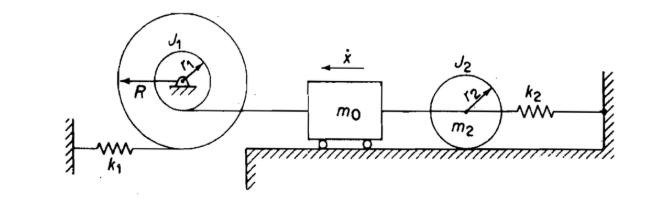

`Equation of motion is given by,`


$$\left(m_{0\;} +m_{2\;} +\frac{J_1 }{r_1^2 }+\frac{J_2 }{r_2^2 }\right)\overset{\ldotp \ldotp }{x} +\left(k_2 +\frac{R^2 }{r_1^2 }k_1 \right)x=0$$


clear all; close all; clc;

`Problem Parameters`

m_0 = 10 ; % mass of cart in kg
m_2 = 5  ; % mass of roller in kg
k_1 = 25 ; % Stiffness of spring1 in N/m
k_2 = 50 ; % Stiffness of spring2 in N/m
R   = 1  ; % Outer Radius of stepped pulley in m
r_1 = 0.5; % Inner Radius of stepped pulley in m
r_2 = 0.5; % Radius of roller in m
J_1 = 5  ; % Moment of Inertia of stepped pulley in kg/(m^2)
J_2 = 2  ; % Moment of Inertia of roller in kg/(m^2)
x_0 = 0  ; % Initial position of m_0 in m
ve_0 = 0.5  ; % Initial velocity of m_0 in m/s

`Setting Time`

simTime    = 200;              % Simulation time in s
tStep      = 0.5;           % Simulation time step
iterations = simTime/tStep;
t          = 1:iterations;

`Pre-allocate variables for acceleration`

x       = zeros(iterations,1);
x(1,:)  = x_0;
ve      = zeros(iterations,1);
ve(1,:) = ve_0;
om      = sqrt(((k_2 + ((R^2)/((r_2)^2))*k_1))/(m_0 + m_2 +(J_1)/((r_1)^2) + (J_2)/((r_2)^2)));
A       = sqrt( (x_0)^2 + (ve_0/om)^2 ); 
phi     = atan(x_0*om/ve_0);

`Set up video`

v           = VideoWriter('Pulley.avi');
v.FrameRate = 100;
open(v);

`Solving and Plotting`

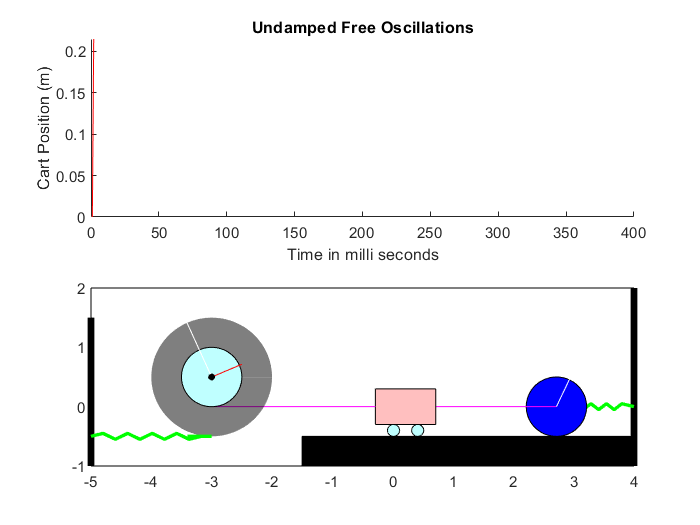

for n=2:(iterations+1)
    
  x(n,:) = A*sin(1.15*pi*om*n + phi);
  
  % Plot everything for the video
  
  subplot(2,1,1)
  hold on;
  plot(t(:,1:n),x(1:n,:),'r')
  xlim([0 iterations])
  xlabel('Time in milli seconds')
  ylabel('Cart Position (m)')
  title('Undamped Free Oscillations');
  
  subplot(2,1,2)
  hold on;
  fill([-5 4 4 -5],[-1 -1 2 2],'w'); % clears background
  plot([4 4],[-1 2],'k', 'LineWidth',4) % wall
  plot([-5 -5],[-1 1.5],'k', 'LineWidth',4) % wall
  fill([-1.5 4 4 -1.5],[-1 -1 -0.5 -0.5],'k'); % Ground
  plot([4, 3.8:((-3.8+x(n,:)+2.3)/10):x(n,:)+2.3, x(n,:)+2.5],...
        [0 0.05 -0.05 .05 -.05 .05 -.05 .05 -.05 0.05 -0.05 0 0 ],'g','LineWidth',2) % spring
  ang=0:0.01:2*pi; 
  theta = x(n,:)/0.5 ;
  xp=0.5*cos(ang); yp=0.5*sin(ang);
  patch(x(n,:)+2.5+xp, yp,'b'); % Roller
  plot([x(n,:)+2.5 x(n,:)+2.5+.5*theta], [0 0.459],'w'); 
  plot(x(n,:)+[2.5 0.5],[0 0],'m');
  fill(x(n,:)+[-0.5 0.5 0.5 -0.5],[-0.3 -0.3 0.3 0.3],'r','facealpha',0.25); % cart
  patch(x(n,:)+0.2+(xp/5), (yp/5)-0.4,'c','facealpha',0.25); %wheel
  patch(x(n,:)-0.2+(xp/5), (yp/5)-0.4,'c','facealpha',0.25); %wheel
  plot([x(n,:)-0.5 -3],[0 0],'m');
  patch(-3+xp, 0.5+yp,'c','facealpha',0.25); % stepped pulley
  patch(-3+[2*xp,xp],0.5+[2*yp,yp],'k','linestyle','none','facealpha',0.5);
  plot([-3 -2.5], [0.5 0.5+.5*theta],'r');
  plot([-3 -3-1*theta], [0.5 1.459],'w');
  plot([-5, -4.8:((4.8+theta-3.6)/8):theta-3.6, -3.4, -3.2,  -3],...
        [-0.5 -0.5+0.05 -.5-0.05 -.5+.05 -.5-.05 -.5+.05 -.5-.05 -.5+.05 -.5-.05 -.5 -.5 -.5 -.5 ],'g','LineWidth',2) % spring
  patch(-3+xp/10, 0.5+yp/10,'k'); %pivot at center of the stepped pulley
  
  
  xlim([-5 4]);
  ylim([-1 2]);
  frame = getframe(gcf);
  writeVideo(v,frame)
 
end


close(v);